% Welcome fellow Matlab users! Let's just dig into Matlab!
% Refer to http://web.cecs.pdx.edu/~gerry/MATLAB/variables/matrices.html.

% This is how you can write one-line comments.

%{ 
    Multi-line comments are enclosed
    between '%{' and '%}'.
%}

% Let's create variables with basic types: integer, double, string, matrices

x = 1  % [try adding a semicolon at the end of expression to supress the output]

x = 1


x = double(102)  % [try changing to int32, uint8, char, string]

x = 102

y = 1*3 + 1/5 + 3^2 - 30 + sqrt(144) + pow2(3)
z = -2.2 + y % [why's it not zero?]

% You can output variables using fprintf and/or disp built-ins.

fprintf('Scalar value (fprintf): %d', x);

Scalar value (fprintf): 102


disp(['Scalar value (disp): ', num2str(x)]);  % [type: help num2str]

Scalar value (disp): 102


% all numerical variable in Matlab are matrices (even scalars!)
[num_rows, cols] = size(x);
fprintf('rows: %d, cols: %d', num_rows, cols);

% string is an array of characters
s = 'Kazan Federal University'

% addressing array's elements is straight-forward
% BUT keep in mind that indexing starts from 1

s(1) % 1st element

disp(['size: ', num2str(size(s))])

% vector is a matrix with either one row or column

v = [1, 4, 2];  % row-vector
disp(v);

v = [1; 4; 2];  % column-vector
disp(v);

v = ones(1, 3);  % [replace 'ones' with 'zeros']
disp(v);

v = ones(3, 1);
disp(v);

v = linspace(1, 5, 3);  % [change 3 to other value and see the result]
disp(v);

% addressing vector elements
v = randi(99, [1, 5]);
disp(v);

v(1) % 1st element
v(size(v, 2))  % [what does size(v, 2) mean?]

v = randi(99, [5, 1]);
disp(v);

v(1)
v(size(v, 1))

% colon notation helps to refer to ranges of elements
x_begin = 1;
x_end = 5;
x_step = 2;  % [set x_step to other values]

v = x_begin:x_end;  % step is 1 by default
disp(v);

v = x_begin:x_step:x_end;
disp(v);

% slices
v = 1:2:10;
disp(v);

disp(v(1:2:3));

disp(v(3:-1:1)); % [TASK] output in reverse order using slices

% vector operations
v1 = [1, 0, 0];
v2 = [0, 1, 0];

disp(v1);

disp(v1 + 2) % addition of a scalar
disp(v1 * 2) % multiplication by a scalar

disp(v1 - v2); % vector subtraction

disp(dot(v1, v2)) % dot product
disp(cross(v1, v2))

disp(v1') % transpose

disp(v1' * v1) % column-vector to row-vector multiplication

% creating matrices
A = [1, 2; 3, 4]

A = [1:2; 3:4]

% addressing elements
A(1, 1)
A(2, 1)

A(1, :) % all columns at 1st row
A(:, 1) % all rows at 1st column

A(:) % all elements expanded in column-wise order

% matrix operations
A = [1, 2; 2 3]

inv(A)

A * inv(A)

inv(A) * A

det(A)

% skew-symmetric matrix (from a vector)
skew([1 2 3])

% transpose
A'

% augmenting
[A, [5; 5]]

[A; [5, 5]]

B = ones(2, 2)

% matrix multiplication
A * B 

% element-wise multiplication
A .* B

% filtering
v = 1:7
v(v > 3)

A = [1 2 0; 2 5 -1; 4 10 -1]

eig(A) % eigen values

svd(A)

% complex numbers
complex(1, 2)

complex(1, 2) + complex(0, -1)

complex(1, 2) * complex(2, 1)

complex(1, 3) / complex(1, 1)

abs(complex(3, 4))  % magnitude

rad2deg(angle(complex(cos(pi/3), sin(pi/3))))

% loops, conditions, etc.
A = int8(ones(3, 2))

for i=1:size(A, 1)
    for j=1:size(A, 2)
        fprintf('row: %d, col: %d, value: %d\n', i, j, A(i, j));
        
        if mod(i, 2) == 0
            disp('Even')
        end
    end
end


ret_val = my_function(3); % custom functions

% Plotting
xs = 1:10;
ys = randi(10, [1, size(xs, 2)]);

% plot 2D graph
plot(xs, ys, 'r-x', 'LineWidth', 2);

hold on; % put on hold current figure

% horizontal line
yline(5, 'k--');

% vertical line
xline(7, 'b--');

% main title
title('2D graph');

% 2D grid
grid("on");

% axis labels
xlabel('x')
ylabel('y');

% legend
legend(['values'])

hold off;  % release current figure

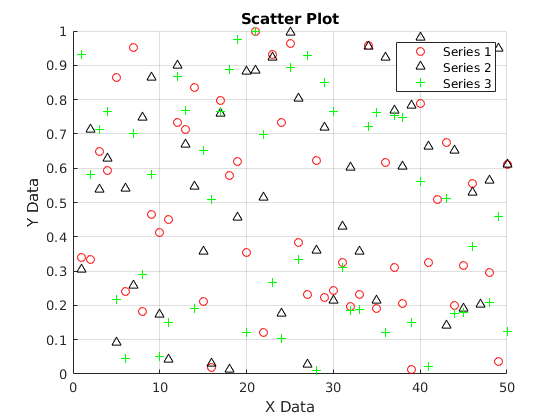

xs = 1:50;
ys1 = rand([1, size(xs, 2)]);
ys2 = rand([1, size(xs, 2)]);
ys3 = rand([1, size(xs, 2)]);

scatter(xs, ys1, 'ro');

hold on;

scatter(xs, ys2, 'k^');
scatter(xs, ys3, 'g+');

title('Scatter Plot');
xlabel('X Data');
ylabel('Y Data');
grid("on");

legend({'Series 1', 'Series 2', 'Series 3'})

hold off;

% Create data for childhood disease cases
measles = [38556 24472 14556 18060 19549 8122 28541 7880 3283 4135 7953 1884];
mumps = [20178 23536 34561 37395 36072 32237 18597 9408 6005 6268 8963 13882];
chickenPox = [37140 32169 37533 39103 33244 23269 16737 5411 3435 6052 12825 23332];

% Create a vertical bar chart using the bar function
figure
bar(1:12, [measles' mumps' chickenPox'], 1)

% Set the axis limits
axis([0 13 0 40000])

set(gca, 'XTick', 1:12)

% Add title and axis labels
title('Childhood diseases by month')
xlabel('Month')
ylabel('Cases (in thousands)')

% Add a legend
legend('Measles', 'Mumps', 'Chicken pox')

function Out = my_function(Input)
    Out = Input + 2
end